clear all;

% Call the script to get the CFD Look Up Table
[wut_cr_lut_data, uvic_cfd_lut_data, uvic_cfd_true_data, uvic_amp_lut_data] = f00_pmtCFDAlgorithmLUT();
% waveforms = f01_pmtCFDWaveforms();
% waveform = waveforms(:,1);

% root_data = readmatrix("C:\Users\miech\Documents\HyperK\Repozytoria\mpmt_teststand\waveforms.csv");
% waveforms = root_data';
% waveforms(isnan(waveforms)) = 0;

janusz_marzec_data_path = "C:\Users\miech\Documents\HyperK\Dane\JMarzec\CFD\C1--hv--10700---00000samples.csv";
jm_data = readmatrix(janusz_marzec_data_path);
waveforms = jm_data';

cfd = [];
cfd.delay = 1;
cfd.gain_delayed = 2;
time_base_ns = 8;
cr_lut_size = length(wut_cr_lut_data);

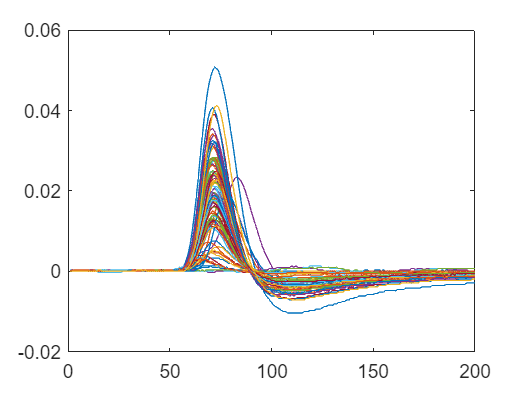

waveform = waveforms(1:32,10);
plot(waveform)

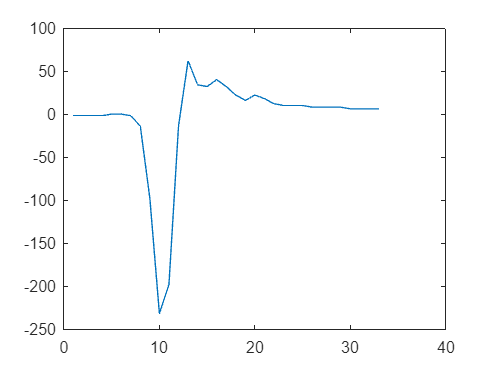

samples = waveform;
delayed = [-cfd.gain_delayed * samples(1:cfd.delay); -cfd.gain_delayed * samples;];
plot(delayed); %title(delayed);

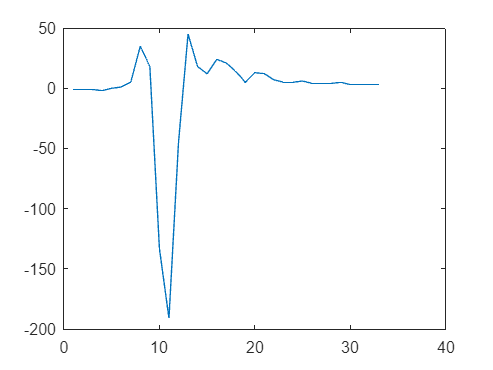


samples = [samples; samples(end-cfd.delay+1:end)];
cf_samples = samples + delayed;
plot(cf_samples); %title(cf_samples)


% Find minimum and maximum of constant fraction waveform and deduct whether we have negative or positive pulses
[~, idx_min] = min(cf_samples);
idx = idx_min;

if idx > 1
    % Find first point  that is above zero
    while true
        % We did - decrease its index by one (i.e. move left)
        idx = idx - 1;
        if (idx == 1)
            break;
        end
        if (cf_samples(idx) >= 0) 
            break;
        end
    end

    % Use linear interpolation to get sub-sample index of the zero-crossing point
    x1 = idx;
    x2 = x1+1;
    y1 = cf_samples(sub2ind(size(cf_samples), x1, 1:size(cf_samples,2)));
    y2 = cf_samples(sub2ind(size(cf_samples), x2, 1:size(cf_samples,2)));
    y_ratio = (double(y1) ./ double(y1-y2));
    % linear interpolation
    cf_time_vector = x1 + y_ratio;
    t0_pos = (cf_time_vector-1)*time_base_ns;
    cf_time_coarse = x1;
    cr = y_ratio;
    
    % perform time correction accordingly to cr value
    cr_idx = round(cr*(cr_lut_size-1))+1;
    if cr_idx <= 0
        cr_idx = 1;
    end
    if cr_idx > cr_lut_size
        cr_idx = cr_lut_size;
    end
    cf_time_ns = t0_pos(1) + wut_cr_lut_data(cr_idx) * 8;
    cf_time = cf_time_ns / 8.0;
    cf_time_min = cf_time_ns/8.0 - (cf_time_coarse - 1);
    % amplitude_cr = samples(x1) * cr_amp_lut_data(cr_idx);
    % amplitude_max = max(samples);
   
    % integration start from first sample
    samples_intergral = 0;
    for idx = 1:numel(samples)
        % falling edge - check if below thr
        if idx > x2 && samples(idx) < 0
            break
        end
        samples_intergral = samples_intergral + samples(idx);
    end

else
    cf_time_ns = NaN;
    cr = NaN;
    amplitude_cr = NaN;
    amplitude_max = NaN;
    samples_intergral = NaN;
end
